clc
clear

load("fourth_iteration_model1.mat")
figure;
nRuns = 8

nRuns = 8

all_runs = [];
sampling_time = linspace(1,3600,3600);

downtime = zeros(1, nRuns)

downtime =      0     0     0     0     0     0     0     0


delta_inspections = zeros(1, nRuns);
average_reward = zeros(1, nRuns)

average_reward =      0     0     0     0     0     0     0     0



for r_index = 1:nRuns
    variable_name = "optimal_run"+string(r_index)+".mat";
    
    load(variable_name)
    
    last_marking = solarfarm.initial_marking;
    last_timestamp = duration;
    
    exe_time = [];
    reward_accumulated = [0];
    total_place_reward = [];
    
    nFiredTransitions = size(results.transitions, 1);
    
    for f_index = 1:nFiredTransitions
        
        if f_index>1
            reward_accumulated(f_index) = reward_accumulated(f_index-1);
        else
            reward_accumulated(f_index) = 0;
        end
        
        current_timestamp = results.timestamps(f_index);
        exe_time(f_index) = seconds(results.timestamps(f_index));
        current_marking = results.markings(f_index,:);
        duration = current_timestamp - last_timestamp;
        transition_chosen = results.transitions(f_index);
        
        marked_places = last_marking~=0;
        reward_accumulated(f_index) = (dot(solarfarm.place_rewards,marked_places) * seconds(duration)) + reward_accumulated(f_index);
        
        
        trans_reward = solarfarm.transition_rewards(solarfarm.find_transition_index(transition_chosen));
        reward_accumulated(f_index) = reward_accumulated(f_index) + trans_reward;
        
        last_timestamp = current_timestamp;
        last_marking = current_marking;
        
        
        
        if exe_time(f_index) > 3600
            results.transitions = results.transitions(1:f_index, :);
            results.markings = results.markings(1:f_index, :);
            results.timestamps = results.timestamps(1:f_index,:);
            break
        end
        
    end
    
    exe_reward_accumulated = reward_accumulated;
    
    hold on
    %plot(exe_time/60, exe_reward_accumulated);
    
    
    all_runs(r_index, :) = interp1(exe_time, exe_reward_accumulated, sampling_time);
    
    running_time = exe_time(end);
    total_reward = exe_reward_accumulated(end);
    nInspections = size(find(startsWith(results.transitions, "Inspect_")), 1);
    downtime(r_index) = (nInspections*200 - total_reward)/running_time;
    nInspectionRound = size(find(startsWith(results.transitions, "InspectedAll")), 1)
    delta_inspections(r_index) = running_time/nInspectionRound;
    average_reward(r_index) = total_reward/running_time;

end

nInspectionRound = 5

nInspectionRound = 6

nInspectionRound = 3

nInspectionRound = 7

nInspectionRound = 7

nInspectionRound = 6

nInspectionRound = 5

nInspectionRound = 7

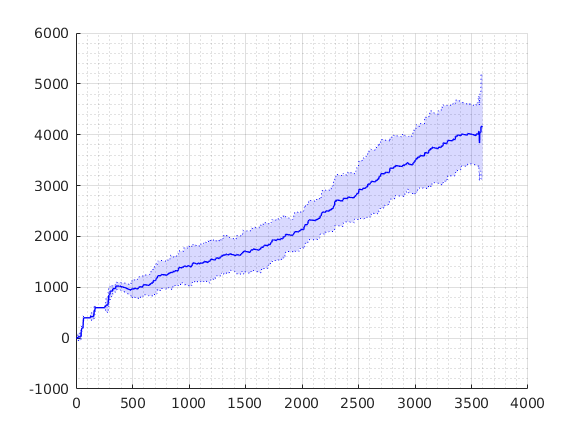


grid on
grid minor

mean_reward = mean(all_runs, 1, 'omitnan');
std_dev = std(all_runs, 'omitnan');

shade(sampling_time, mean_reward+std_dev,'b:', sampling_time, mean_reward-std_dev,'b:', 'FillType', [1 2], 'FillColor', 'b', 'FillAlpha', 0.15)
hold on
plot(sampling_time, mean_reward,'b', 'LineWidth', 1.0)

grid on;


save("execution_optimal_policy.mat", "all_runs")
save("execution_optimal_policy_metrics.mat", "downtime", "delta_inspections", "average_reward")

clear
load("fourth_iteration_model1.mat")
nRuns = 5;
all_runs = [];
sampling_time = linspace(1,3600,3600);
downtime = zeros(1, nRuns)

downtime =      0     0     0     0     0


delta_inspections = zeros(1, nRuns);
average_reward = zeros(1, nRuns)

average_reward =      0     0     0     0     0



for r_index = 1:nRuns
    variable_name = "handcrafted_run"+string(r_index)+".mat";
    
    load(variable_name)
    
    last_marking = solarfarm.initial_marking;
    last_timestamp = duration;
    
    exe_time = [];
    reward_accumulated = [0];
    total_place_reward = [];
    
    nFiredTransitions = size(results.transitions, 1);
    
    for f_index = 1:nFiredTransitions
        
        if f_index>1
            reward_accumulated(f_index) = reward_accumulated(f_index-1);
        else
            reward_accumulated(f_index) = 0;
        end
        
        current_timestamp = results.timestamps(f_index);
        exe_time(f_index) = seconds(results.timestamps(f_index));
        current_marking = results.markings(f_index,:);
        duration = current_timestamp - last_timestamp;
        transition_chosen = results.transitions(f_index);
        
        marked_places = last_marking~=0;
        reward_accumulated(f_index) = (dot(solarfarm.place_rewards,marked_places) * seconds(duration)) + reward_accumulated(f_index);
        
        
        trans_reward = solarfarm.transition_rewards(solarfarm.find_transition_index(transition_chosen));
        reward_accumulated(f_index) = reward_accumulated(f_index) + trans_reward;
        
        last_timestamp = current_timestamp;
        last_marking = current_marking;
        
        
        
        if exe_time(f_index) > 3600
            results.transitions = results.transitions(1:f_index, :);
            results.markings = results.markings(1:f_index, :);
            results.timestamps = results.timestamps(1:f_index,:);
            break
        end
        
    end
    
    exe_reward_accumulated = reward_accumulated;
    
    running_time = exe_time(end);
    total_reward = exe_reward_accumulated(end);
    nInspections = size(find(startsWith(results.transitions, "Inspect_")), 1);
    downtime(r_index) = (nInspections*200 - total_reward)/running_time;
    nInspectionRound = size(find(startsWith(results.transitions, "InspectedAll")), 1)
    delta_inspections(r_index) = running_time/nInspectionRound;
    average_reward(r_index) = total_reward/running_time;
    
    %plot(exe_time/60, exe_reward_accumulated);
    [~, ind] = unique(exe_time);
    
    all_runs(r_index, :) = interp1(exe_time(ind), exe_reward_accumulated(ind), sampling_time);
end

nInspectionRound = 6

nInspectionRound = 6

nInspectionRound = 5

nInspectionRound = 6

nInspectionRound = 5

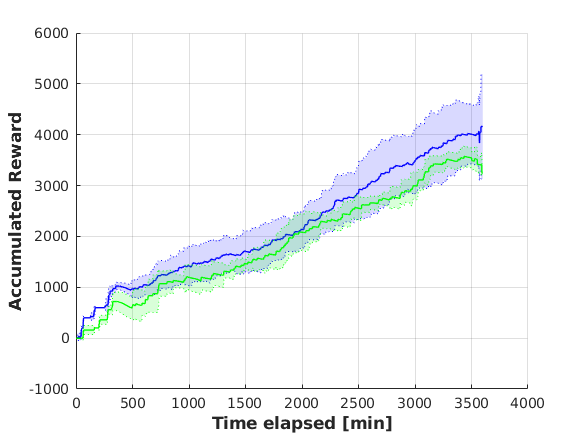

xlabel("Time elapsed [min]",'FontSize',12,'FontWeight','bold')
ylabel("Accumulated Reward",'FontSize',12,'FontWeight','bold')
grid on
grid minor

mean_reward = mean(all_runs, 1, 'omitnan');
std_dev = std(all_runs, 'omitnan');
upper_bound = mean_reward + std_dev;
lower_bound = mean_reward - std_dev;
shade(sampling_time, lower_bound, sampling_time, upper_bound, 'LineStyle',':', 'Color', 'g','FillType', [1 2; 2 1], 'FillColor', 'g','FillAlpha', 0.15)
hold on
plot(sampling_time, mean_reward,'Color', 'g','LineWidth', 1.0)

grid on;


save("execution_handcrafted_policy.mat", "all_runs")
save("execution_handcrafted_policy_metrics.mat", "downtime", "delta_inspections", "average_reward")

clear
load("fourth_iteration_model1.mat")
nRuns = 5;
all_runs = [];
sampling_time = linspace(1,3600,3600);
downtime = zeros(1, nRuns)

downtime =      0     0     0     0     0


delta_inspections = zeros(1, nRuns);
average_reward = zeros(1, nRuns)

average_reward =      0     0     0     0     0



for r_index = 1:nRuns
    variable_name = "random_run"+string(r_index)+".mat";
    
    load(variable_name)
    
    last_marking = solarfarm.initial_marking;
    last_timestamp = duration;
    
    exe_time = [];
    reward_accumulated = [0];
    total_place_reward = [];
    
    nFiredTransitions = size(results.transitions, 1);
    
    for f_index = 1:nFiredTransitions
        
        if f_index>1
            reward_accumulated(f_index) = reward_accumulated(f_index-1);
        else
            reward_accumulated(f_index) = 0;
        end
        
        current_timestamp = results.timestamps(f_index);
        exe_time(f_index) = seconds(results.timestamps(f_index));
        current_marking = results.markings(f_index,:);
        duration = current_timestamp - last_timestamp;
        transition_chosen = results.transitions(f_index);
        
        marked_places = last_marking~=0;
        reward_accumulated(f_index) = (dot(solarfarm.place_rewards,marked_places) * seconds(duration)) + reward_accumulated(f_index);
        
        
        trans_reward = solarfarm.transition_rewards(solarfarm.find_transition_index(transition_chosen));
        reward_accumulated(f_index) = reward_accumulated(f_index) + trans_reward;
        
        last_timestamp = current_timestamp;
        last_marking = current_marking;
        
        
        
        if exe_time(f_index) > 3600
            results.transitions = results.transitions(1:f_index, :);
            results.markings = results.markings(1:f_index, :);
            results.timestamps = results.timestamps(1:f_index,:);
            break
        end
        
    end
    
    exe_reward_accumulated = reward_accumulated;
    
    %plot(exe_time/60, exe_reward_accumulated);
    [~, ind] = unique(exe_time);
    
    all_runs(r_index, :) = interp1(exe_time(ind), exe_reward_accumulated(ind), sampling_time);

    running_time = exe_time(end);
    total_reward = exe_reward_accumulated(end);
    nInspections = size(find(startsWith(results.transitions, "Inspect_")), 1);
    downtime(r_index) = (nInspections*200 - total_reward)/running_time;
    nInspectionRound = size(find(startsWith(results.transitions, "InspectedAll")), 1)
    delta_inspections(r_index) = running_time/nInspectionRound;
    average_reward(r_index) = total_reward/running_time;

end

nInspectionRound = 1

nInspectionRound = 1

nInspectionRound = 1

nInspectionRound = 1

nInspectionRound = 1

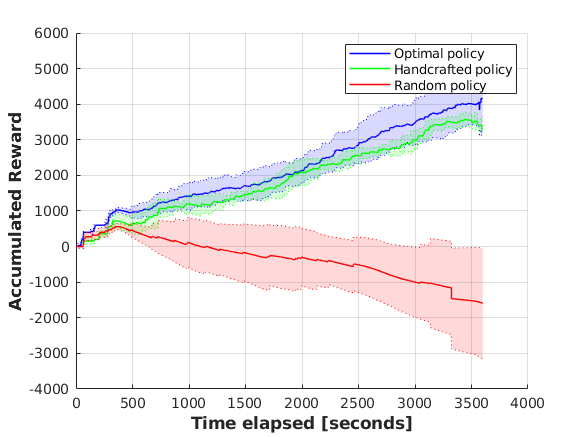


mean_reward = mean(all_runs, 1, 'omitnan');
std_dev = std(all_runs, 'omitnan');
upper_bound = mean_reward + std_dev;
lower_bound = mean_reward - std_dev;
shade(sampling_time, lower_bound, sampling_time, upper_bound, 'LineStyle',':', 'Color', 'r','FillType', [1 2; 2 1], 'FillColor', 'r','FillAlpha', 0.15)
hold on
plot(sampling_time, mean_reward,'Color', 'r','LineWidth', 1.0)
legend('','','','', '', '','','', '', '', 'Optimal policy', '', '','','','', '', '', '', '', '', 'Handcrafted policy', '', '', '','', '', 'Random policy')

xlabel("Time elapsed [seconds]",'FontSize',12,'FontWeight','bold')
ylabel("Accumulated Reward",'FontSize',12,'FontWeight','bold')

grid on;


save("execution_random_policy.mat", "all_runs")
save("execution_random_policy_metrics.mat", "downtime", "delta_inspections", "average_reward")